load ("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map.mat");
network = load("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\DL\mpnet", "mpnet");

mpnet = network.mpnet

mpnet =   mpnetSE2 with properties:

     StateBounds: [3×2 double]
     LossWeights: [100 100 0]
    EncodingSize: [10 10]
       NumInputs: 108
      NumOutputs: 4
         Network: [1×1 dlnetwork]


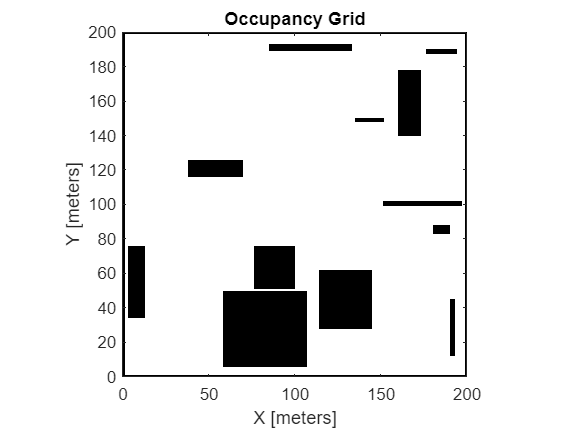

map = occupancyMap(omap);
show(map)

ss = stateSpaceSE2;
ss.StateBounds = [[0 200]; [0 200]; [-3.1416 3.1416]];

stateSamplerDL = stateSamplerMPNET(ss,mpnet);



start = [40 70 0];
goal = [180 30 0];

stateSamplerDL.Environment = map;
stateSamplerDL.StartState = start;
stateSamplerDL.GoalState = goal;

stateValidator = validatorOccupancyMap(ss,Map=map);
stateValidator.ValidationDistance = 0.1;

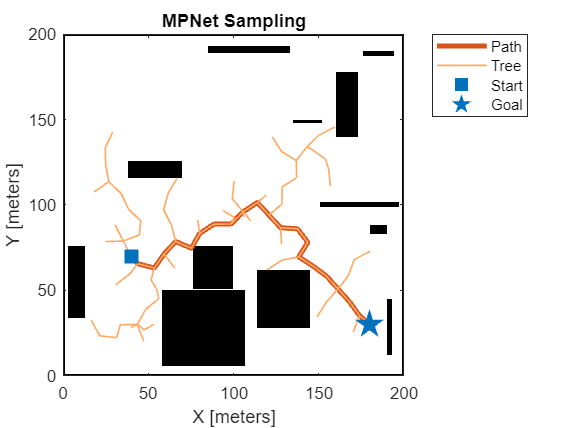



plannerDLSampling = plannerRRTStar(ss,stateValidator,MaxConnectionDistance=10,StateSampler=stateSamplerDL);
[pathDLSampling,solutionInfoDLSampling] = plan(plannerDLSampling,start,goal);

% Visualize results with deep learning based sampling
figure
show(map);
hold on;
plot(pathDLSampling.States(:,1),pathDLSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoDLSampling.TreeData(:,1),solutionInfoDLSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:})
plot(goal(1),goal(2),plannerLineSpec.goal{:})
legend(Location="northeastoutside")
title("MPNet Sampling")

% Number of runs to benchmark the planner
runCount = 30;

% Create plannerBenchmark object
pb = plannerBenchmark(stateValidator,start,goal);

% Create function handles to create planners for uniform sampling and deep
% learning-based sampling
plannerUniformSamplingFcn = @(stateValidator)plannerRRT(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=3);
plannerMPNetSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=3,StateSampler=stateSamplerDL);

% Create plan function
plnFcn = @(initOut,s,g)plan(initOut,s,g);

% Added both planners to plannerBenchmark object
addPlanner(pb,plnFcn,plannerUniformSamplingFcn,PlannerName="Uniform");
addPlanner(pb,plnFcn,plannerMPNetSamplingFcn,PlannerName="MPNet");

% Run planners for specified runCount
runPlanner(pb,runCount)

Initializing Uniform ...
Done.
Planning a path from the start pose (40 70 0) to the goal pose (180 30 0) using Uniform.
Executing run 1.
Executing run 2.
Executing run 3.
Executing run 4.
Executing run 5.
Executing run 6.
Executing run 7.
Executing run 8.
Executing run 9.
Executing run 10.
Executing run 11.
Executing run 12.
Executing run 13.
Executing run 14.
Executing run 15.
Executing run 16.
Executing run 17.
Executing run 18.
Executing run 19.
Executing run 20.
Executing run 21.
Executing run 22.
Executing run 23.
Executing run 24.
Executing run 25.
Executing run 26.
Executing run 27.
Executing run 28.
Executing run 29.
Executing run 30.
Initializing MPNet ...
Done.
Planning a path from the start pose (40 70 0) to the goal pose (180 30 0) using MPNet.
Executing run 1.
Executing run 2.
Executing run 3.
Executing run 4.
Executing run 5.
Executing run 6.
Executing run 7.
Executing run 8.
Executing run 9.
Executing run 10.
Executing run 11.
Executing run 12.
Executing run 13.
Executin

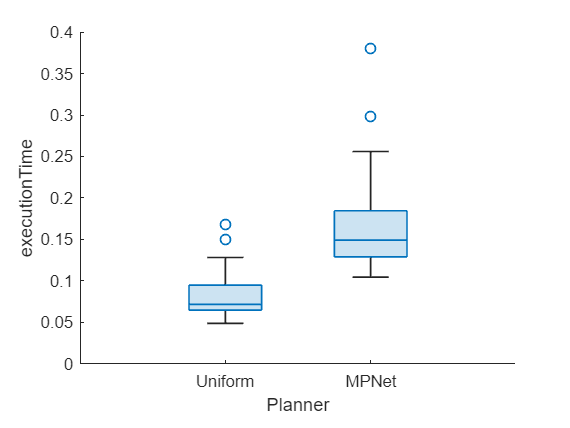


figure
show(pb,"executionTime")

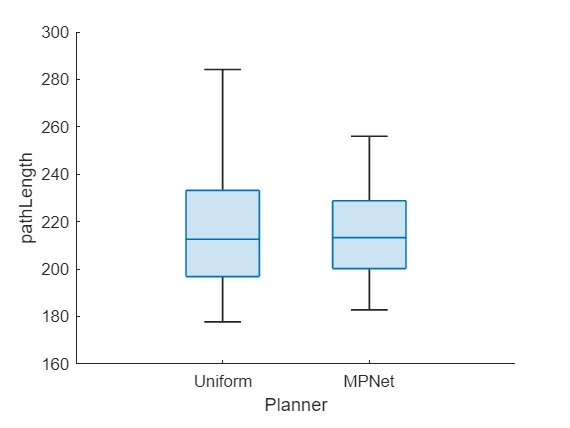

figure
show(pb,"pathLength")

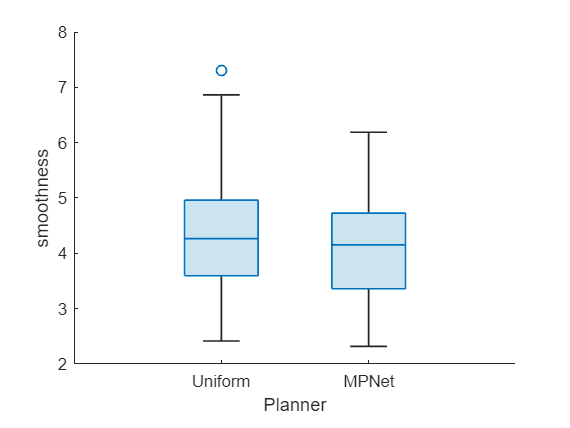

figure
show(pb,"smoothness")

pb.PlannerOutput.Uniform.InitializationOutput

ans =   plannerRRT with properties:

               StateSpace: [1×1 stateSpaceSE2]
           StateValidator: [1×1 validatorOccupancyMap]
             StateSampler: [1×1 stateSamplerUniform]
          MaxNumTreeNodes: 10000
            MaxIterations: 10000
    MaxConnectionDistance: 3
           GoalReachedFcn: @nav.algs.checkIfGoalIsReached
                 GoalBias: 0.0500
